# Experimento das rodas - Selecionado

## Importar dados

clear
load("exp_rodas.mat")

## Cabeçalho

f = freq;
ts = 0.01;
t_uni = 0:ts:length(u)*ts-ts;
limx = [0,120];
limy = [min(min(yr), min(yl)) max(max(yr), max(yl))];
limyv = [min(min(dyr), min(dyl)) max(max(dyr), max(dyl))];
opt = procestOptions("InitialCondition", "zero");
tpl = "Posição da roda Esquerda";
tpr = "Posição da roda Direita";
tvl = "Velocidade da roda Esquerda";
tvr = "Velocidade da roda Direita";
lprad = "Posição (rad)";
lvrads = "Velocidade (rad/s)";
lem = ["Experimento", "Modelo"];
lt = "Tempo (s)";

### Dados de simulação e entrada

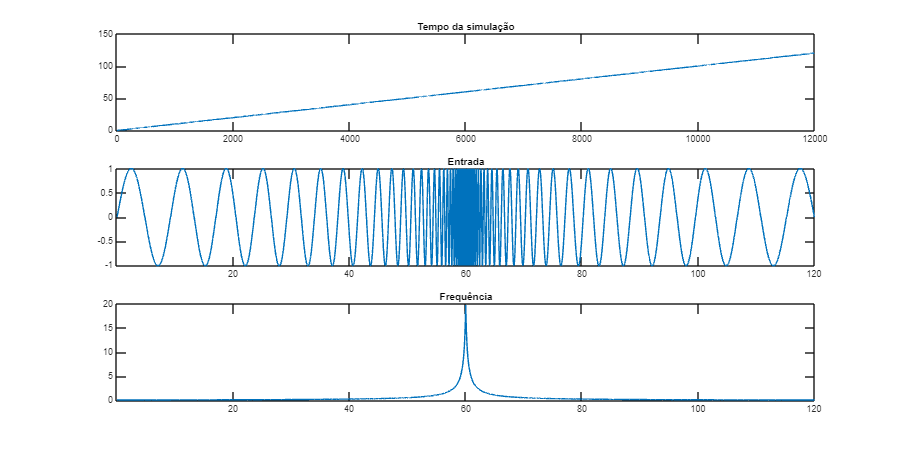

figure("Position", [403 146 1200 600])

subplot(3,1,1); plot(t);     title("Tempo da simulação");
subplot(3,1,2); plot(t, u);  title("Entrada");            xlim([t(1) t(end)]);
subplot(3,1,3); plot(t, f);  title("Frequência");         xlim([t(1) t(end)]);

## Modelagem por dados de posição

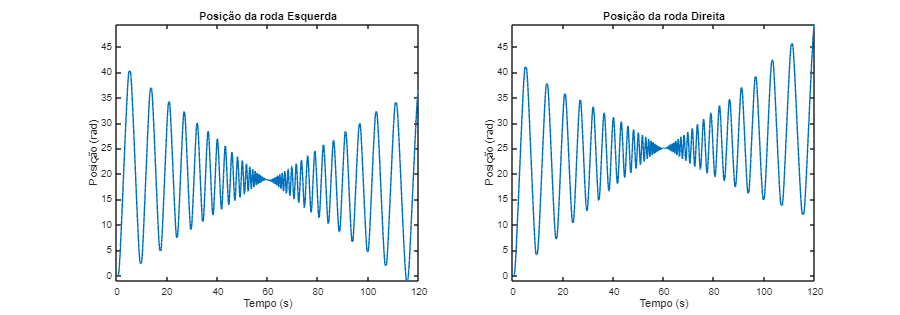

figure("Position", [403 146 1200 420])

subplot(1,2,1); plot(t, yl); title(tpl);  xlabel(lt); ylabel(lprad); xlim(limx); ylim(limy);
subplot(1,2,2); plot(t, yr); title(tpr);  xlabel(lt); ylabel(lprad); xlim(limx); ylim(limy);

### Estimativa do modelo de posição

dados_l = iddata(yl, u, ts); G_l = procest(dados_l, "P1I", opt); tf(G_l)

ans =
 
  From input "u1" to output "y1":
      12.93
  --------------
  0.2097 s^2 + s
 
Continuous-time transfer function.
Model Properties


dados_r = iddata(yr, u, ts); G_r = procest(dados_r, "P1I", opt); tf(G_r)

ans =
 
  From input "u1" to output "y1":
      12.88
  --------------
  0.1952 s^2 + s
 
Continuous-time transfer function.
Model Properties


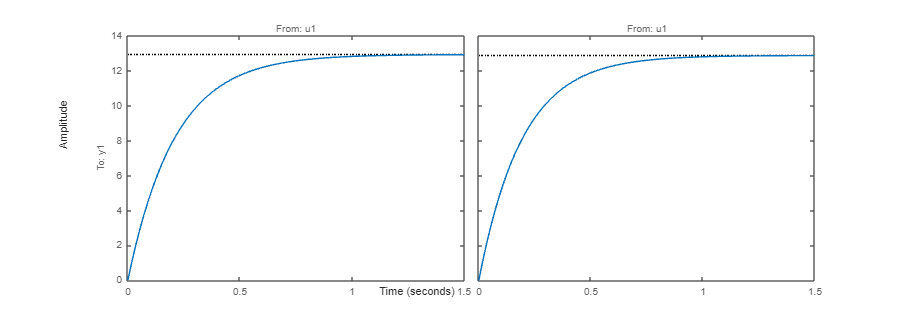

figure("Position", [1 1 1000 500])
impulse([G_l, G_r])

#### Comparação com modelo

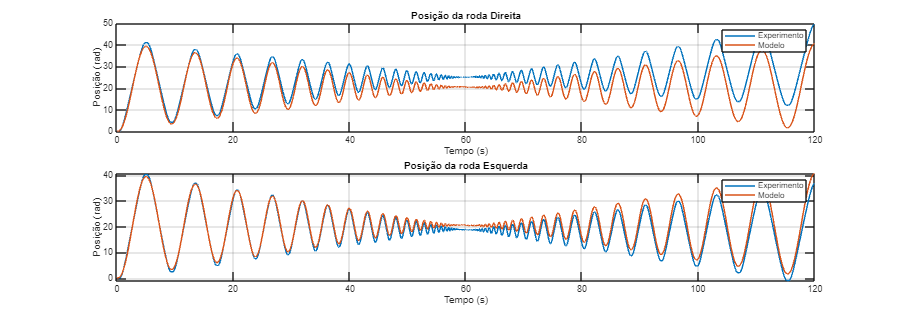

y_l = lsim(G_l, u, t_uni);
y_r = lsim(G_r, u, t_uni);

figure("Position", [403 146 1200 420])
subplot(2,1,1); plot(t_uni, yr); hold on; plot(t_uni, y_r); grid on; xlim(limx); legend(lem); title(tpr); ylabel(lprad); xlabel(lt);
subplot(2,1,2); plot(t_uni, yl); hold on; plot(t_uni, y_l); grid on; xlim(limx); legend(lem); title(tpl); ylabel(lprad); xlabel(lt);

## Modelagem por dados de velocidade

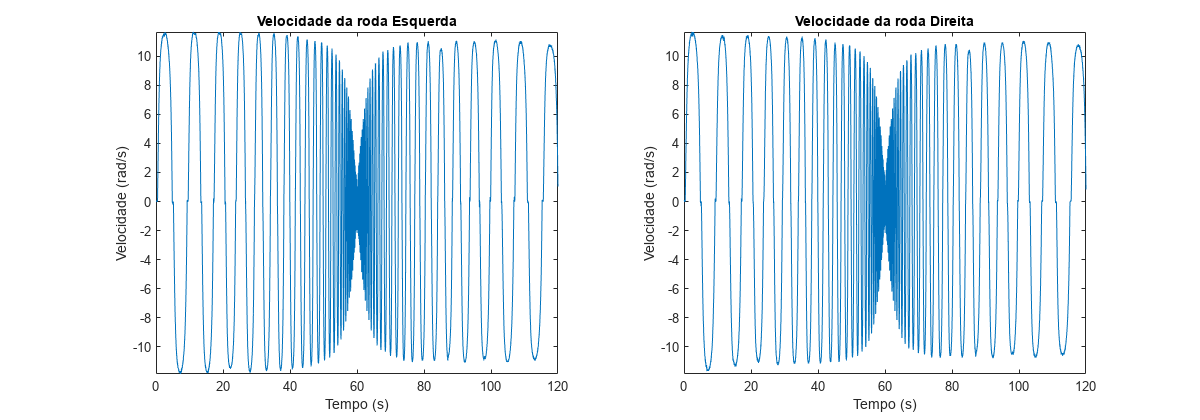

figure("Position", [403 146 1200 420]);

subplot(1,2,1); plot(t, dyl); title(tvl);  xlim(limx); ylim(limyv); xlabel(lt); ylabel(lvrads);
subplot(1,2,2); plot(t, dyr); title(tvr);  xlim(limx); ylim(limyv); xlabel(lt); ylabel(lvrads);

### Estimativa do modelo de velocidade

dados_lv = iddata(dyl, u, ts); G_lv = procest(dados_lv, "P1", opt); tf(G_lv)
dados_rv = iddata(dyr, u, ts); G_rv = procest(dados_rv, "P1", opt); tf(G_rv)
figure("Position", [1 1 1000 500])
step([G_lv, G_rv])

#### Comparação com modelo

dy_l = lsim(G_lv, u, t_uni);
dy_r = lsim(G_rv, u, t_uni);

figure("Position", [403 146 1200 420])
subplot(2,1,1); plot(t_uni, dyr); hold on; plot(t_uni, dy_r); grid on; xlim(limx); legend(lem); title(tvr); ylabel(lvrads); xlabel(lt);
subplot(2,1,2); plot(t_uni, dyl); hold on; plot(t_uni, dy_l); grid on; xlim(limx); legend(lem); title(tvl); ylabel(lvrads); xlabel(lt);

## Exportar dados

- O modelo escolhido foi o de posição para a roda esquerda

zpk(G_l)
K_rodas = ans.K
taus = -1./ans.P{1}
tau = taus(1)
save("tf_rodas.mat", "K_rodas", "tau")